# ESA Signals Acoustic Modem Project

#### Elvis Wolcott and Melissa Kazazic

Deliverables:

1. A brief report that includes an introduction, block diagram, equations used, graphs of signals in the time domain, and graphs of signals in the frequency domain.

2. Link to audio recordings if you produced new ones.

3. Your code.

4. Short demo video (2 minutes or less)

Start with hello example.

clear
load('long_modem_rx.mat');
symbol_period = 100;

y_r =    -0.1146
   -0.0601
   -0.1130
    0.3098
   -0.1135
    0.0647
    0.0142
   -0.0973
    0.0289
   -0.0994


Play and plot initial graphs of signal

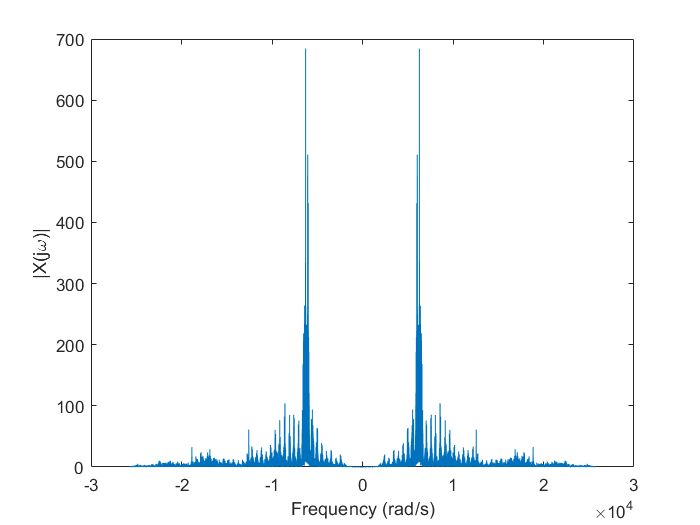

soundsc(y_r,Fs)
plot_ft_rad(y_r,Fs);

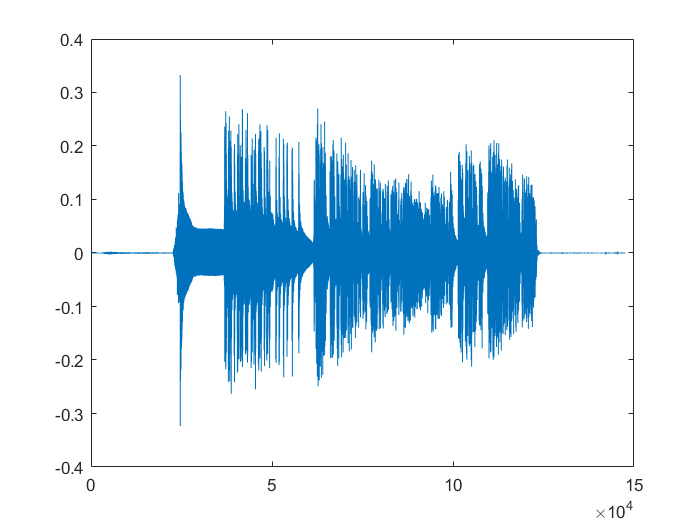

figure()
plot(y_r)

Find the start of the signal

index = find_start_of_signal(y_r,x_sync)

index = 22586

Trim according to start of signal

y_r_crop = y_r(index+length(x_sync):end);

Play and plot cropped signal

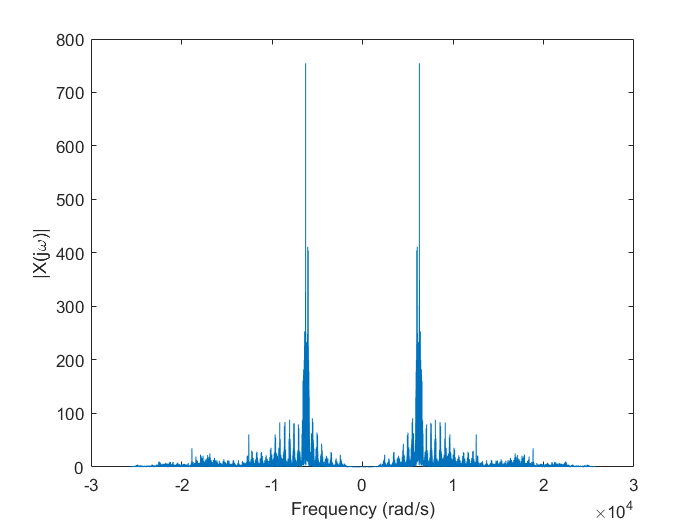

soundsc(y_r_crop,Fs)
plot_ft_rad(y_r_crop,Fs);

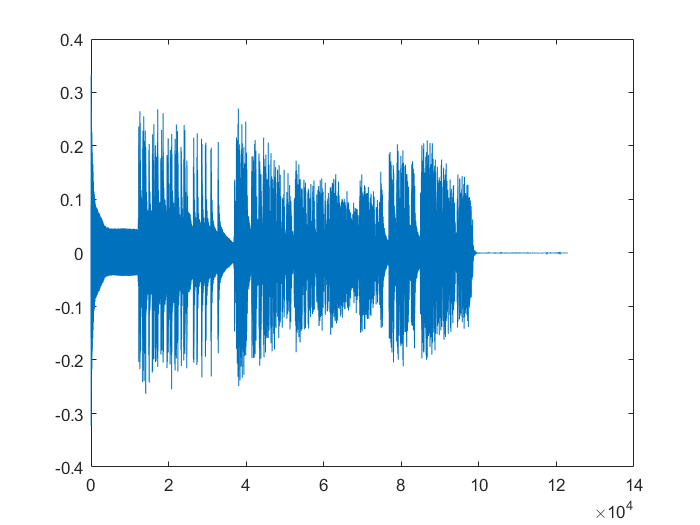

figure()
plot(y_r_crop)

Frequency Shift

t = (0:length(y_r_crop)-1)';
cos_fc = cos(2*pi*f_c/Fs*t);
y_shifted = y_r_crop.*cos_fc

y_shifted =     0.0892
    0.0865
    0.0004
    0.0215
    0.0786
   -0.0005
   -0.0073
    0.0153
   -0.1053
   -0.1038


Play and plot shifted signal

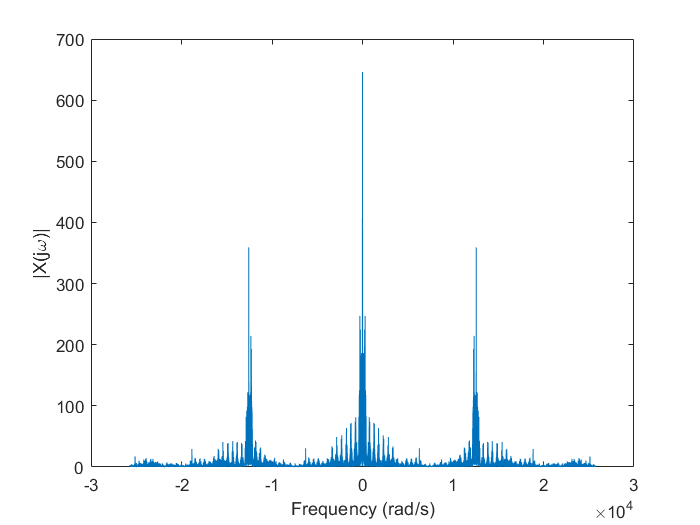

soundsc(y_shifted,Fs)
plot_ft_rad(y_shifted,Fs);

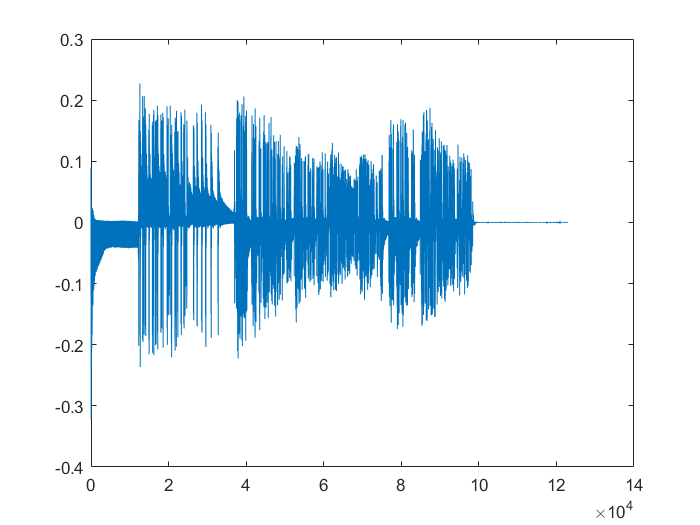

figure()
plot(y_shifted)

Filter shifted signal

y_filtered = lowpass(y_shifted, 1/50);

Play and plot filtered signal

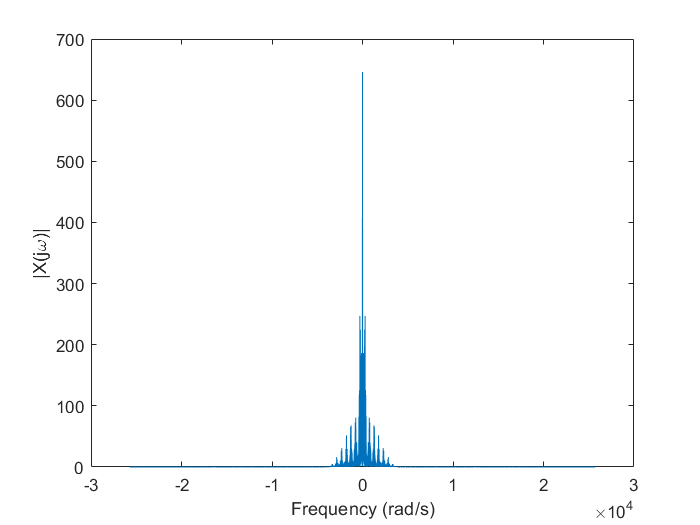

soundsc(y_filtered,Fs)
plot_ft_rad(y_filtered,Fs);

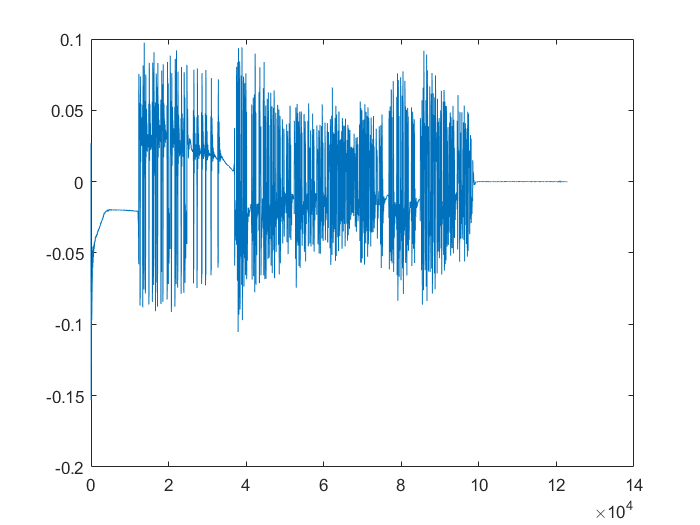

figure()
plot(y_filtered)

sz = floor(length(y_filtered)/100)-1;
bits = zeros(sz, 1);
for i=1:sz
    chunk = (i-1)*100;
    start = chunk + 5;
    cend = chunk + 95;
    bits(i) = mean(y_filtered(start:cend));
end
bits_raw = bits;
bits = bits > 0;

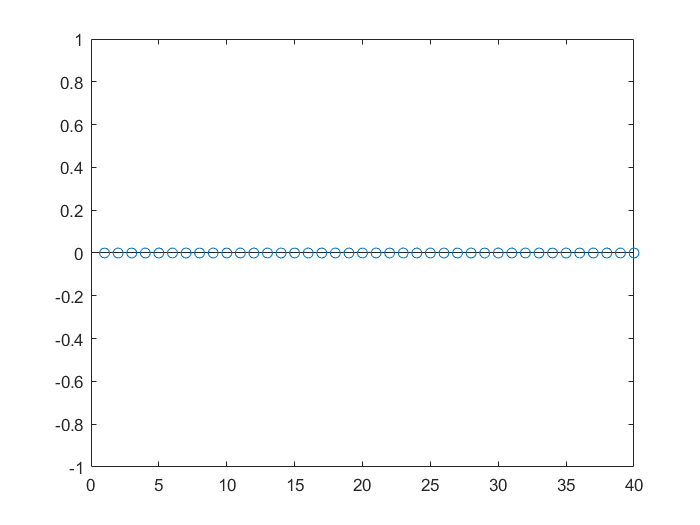

stem(bits(1:40))

% temprary hack
% whole thing doesn't work :< - this seems like a challenge to transmitting
% arbitrary length messages
% BitsToString(bits(1:end-mod(length(bits),8)))
BitsToString(bits(1:msg_length*8))

sz_binary = 984

ans = 'The answer to the Ultimate Question of Life, the Universe, and Everything is 42. The question to the ultimate answer is ...'